Confirm that the amount of glucose that's going towards protein production is correct in the IMM904 model

All lines here assume alpha = 0.1

%build and optimize a model
v = getOptVars();
v.alpha = .010;

model_default = load('C:\sync\biomes\models\Scerevisiae_iMM904.mat'); %Saccaromyces cerevisiae iMM904 
model_default = model_default.model;

%turn off other carbon sources
cex = {'EX_arab__D_e' 'EX_arab__L_e' 'EX_cit_e' 'EX_for_e' 'EX_fru_e' 'EX_fum_e' 'EX_gal_e' ...
    'EX_glc__L_e' 'EX_glu__L_e' 'EX_glx_e' 'EX_glyc_e' 'EX_lac__D_e' 'EX_lac__L_e' 'EX_mal__L_e' ...
    'EX_malt_e' 'EX_man_e' 'EX_sbt__D_e' 'EX_sbt__L_e' 'EX_succ_e' 'EX_sucr_e' 'EX_xyl_e' 'EX_xylt_e'};
for i = 1:length(cex)
    model_default.lb(stridx(cex{i},model.rxns)) = 0;
end

model = buildScerevisiaeModel(v,model_default,'carbonTestModel','f');

produce_enzyme	49 ala__L_c + 7 arg__L_c + 28 asn__L_c + 26 asp__L_c + 4040 atp_c + 22 cys__L_c + 17 gln__L_c + 8 glu__L_c + 62 gly_c + 2020 gtp_c + 4 his__L_c + 17 ile__L_c + 25 leu__L_c + 16 lys__L_c + 9 met__L_c + 16 phe__L_c + 14 pro__L_c + 65 ser__L_c + 62 thr__L_c + 8 trp__L_c + 20 tyr__L_c + 30 val__L_c 	->	4040 adp_c + 2020 gdp_c + enzyme_c 
EX_enzyme_e	enzyme_e 	<=>	


changeCobraSolver('gurobi');


 > Gurobi interface added to MATLAB path.
 > gurobi (version 751) is compatible and fully tested with MATLAB R2017b on your operating system.



opt = optimizeCbModel(model);
opt.f

ans = 0.1585

glcex = stridx('EX_glc__D_e',model.rxns); %glucose exchange reaction
obj = find(model.c); %objective reaction;
opt.x(obj)

ans = 0.1585

produceenz = stridx('produce_enzyme',model.rxns); %enzyme production reaction
opt.x(produceenz)

ans = 0.0016

%secreteenz = stridx('secrete_enzyme',model.rxns); %enzyme transport reaction
%opt.x(secreteenz)
enzex = stridx('EX_enzyme_e',model.rxns); %enzyme exchange reaction
opt.x(enzex)

ans = 0.0016

Ideally, 10% of carbon should be going towards enzyme production.

Find the amount reduction in the objective reaction

opt_default = optimizeCbModel(model_default);
objpct = opt.f/opt_default.f

objpct = 0.5504

%plot the fitness reduction across alphas in the proportional model
alphas = [.01:.05:.99];
fprop = zeros(1,length(alphas));
for i = 1:length(alphas)
    v.alpha = alphas(i);
    m = buildScerevisiaeModel(v,model_default,'temp','p');
    o = optimizeCbModel(m);
    fprop(i) = o.f;
end

produce_enzyme	49 ala__L_c + 7 arg__L_c + 28 asn__L_c + 26 asp__L_c + 4040 atp_c + 22 cys__L_c + 17 gln__L_c + 8 glu__L_c + 62 gly_c + 2020 gtp_c + 4 his__L_c + 17 ile__L_c + 25 leu__L_c + 16 lys__L_c + 9 met__L_c + 16 phe__L_c + 14 pro__L_c + 65 ser__L_c + 62 thr__L_c + 8 trp__L_c + 20 tyr__L_c + 30 val__L_c 	->	4040 adp_c + 2020 gdp_c + enzyme_c 
secrete_enzyme	0.99 biomass_pseudo + 0.01 enzyme_c 	->	0.01 enzyme_e 
EX_enzyme_e	enzyme_e 	<=>	
produce_enzyme	49 ala__L_c + 7 arg__L_c + 28 asn__L_c + 26 asp__L_c + 4040 atp_c + 22 cys__L_c + 17 gln__L_c + 8 glu__L_c + 62 gly_c + 2020 gtp_c + 4 his__L_c + 17 ile__L_c + 25 leu__L_c + 16 lys__L_c + 9 met__L_c + 16 phe__L_c + 14 pro__L_c + 65 ser__L_c + 62 thr__L_c + 8 trp__L_c + 20 tyr__L_c + 30 val__L_c 	->	4040 adp_c + 2020 gdp_c + enzyme_c 
secrete_enzyme	0.94 biomass_pseudo + 0.06 enzyme_c 	->	0.06 enzyme_e 
EX_enzyme_e	enzyme_e 	<=>	
produce_enzyme	49 ala__L_c + 7 arg__L_c + 28 asn__L_c + 26 asp__L_c + 4040 atp_c + 22 cys__L_c + 17 gln_

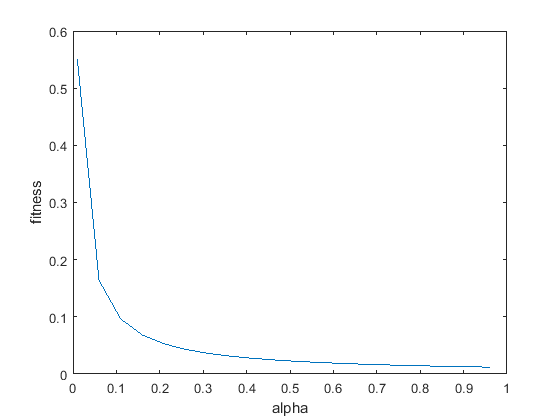

plot(alphas,fprop/opt_default.f)
xlabel('alpha')
ylabel('fitness')

%plot the fitness reduction across alphas in the fixed model
alphas = [.01:.05:.99];
ffixed = zeros(1,length(alphas));
for i = 1:length(alphas)
    v.alpha = alphas(i);
    m = buildScerevisiaeModel(v,model_default,'temp','f');
    o = optimizeCbModel(m);
    ffixed(i) = o.f;
end

produce_enzyme	49 ala__L_c + 7 arg__L_c + 28 asn__L_c + 26 asp__L_c + 4040 atp_c + 22 cys__L_c + 17 gln__L_c + 8 glu__L_c + 62 gly_c + 2020 gtp_c + 4 his__L_c + 17 ile__L_c + 25 leu__L_c + 16 lys__L_c + 9 met__L_c + 16 phe__L_c + 14 pro__L_c + 65 ser__L_c + 62 thr__L_c + 8 trp__L_c + 20 tyr__L_c + 30 val__L_c 	->	4040 adp_c + 2020 gdp_c + enzyme_c 
EX_enzyme_e	enzyme_e 	<=>	
produce_enzyme	49 ala__L_c + 7 arg__L_c + 28 asn__L_c + 26 asp__L_c + 4040 atp_c + 22 cys__L_c + 17 gln__L_c + 8 glu__L_c + 62 gly_c + 2020 gtp_c + 4 his__L_c + 17 ile__L_c + 25 leu__L_c + 16 lys__L_c + 9 met__L_c + 16 phe__L_c + 14 pro__L_c + 65 ser__L_c + 62 thr__L_c + 8 trp__L_c + 20 tyr__L_c + 30 val__L_c 	->	4040 adp_c + 2020 gdp_c + enzyme_c 
EX_enzyme_e	enzyme_e 	<=>	
produce_enzyme	49 ala__L_c + 7 arg__L_c + 28 asn__L_c + 26 asp__L_c + 4040 atp_c + 22 cys__L_c + 17 gln__L_c + 8 glu__L_c + 62 gly_c + 2020 gtp_c + 4 his__L_c + 17 ile__L_c + 25 leu__L_c + 16 lys__L_c + 9 met__L_c + 16 phe__L_c + 14 pro__L_c + 

plot(alphas,ffixed/opt_default.f)
xlabel('alpha')
ylabel('fitness')

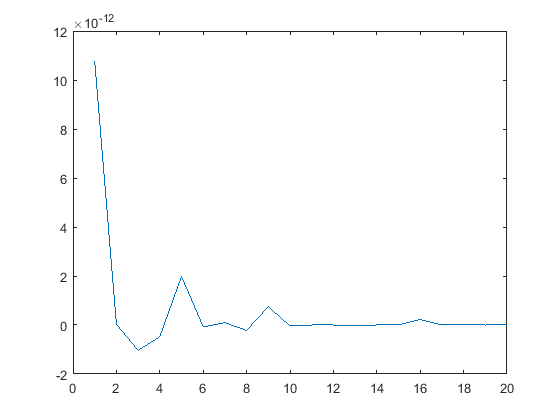


plot(ffixed - fprop)